# Prewitt's operator


% Read the image and convert to double for precision in calculation
aa = rgb2gray(imread('DK.jpg')); 
a = double(aa);

[row, col] = size(a);

% Define Prewitt Masks
% w1 is the horizontal gradient mask
% w2 is the vertical gradient mask
w2 = [-1 0 1; -1 0 1; -1 0 1];
w1 = [-1 -1 -1; 0 0 0; 1 1 1];

% Manual Convolution using nested loops
for x = 2:1:row-1
    for y = 2:1:col-1
        
        % Calculate Horizontal Gradient (a1)
        a1(x,y) = w1(1)*a(x-1,y-1) + w1(2)*a(x-1,y) + w1(3)*a(x-1,y+1) + ...
                  w1(4)*a(x,y-1)   + w1(5)*a(x,y)   + w1(6)*a(x,y+1)   + ...
                  w1(7)*a(x+1,y-1) + w1(8)*a(x+1,y) + w1(9)*a(x+1,y+1);
              
        % Calculate Vertical Gradient (a2)
        a2(x,y) = w2(1)*a(x-1,y-1) + w2(2)*a(x-1,y) + w2(3)*a(x-1,y+1) + ...
                  w2(4)*a(x,y-1)   + w2(5)*a(x,y)   + w2(6)*a(x,y+1)   + ...
                  w2(7)*a(x+1,y-1) + w2(8)*a(x+1,y) + w2(9)*a(x+1,y+1);
    end
end

% The final gradient image (combined magnitude)
a3 = a1 + a2; 

## Display Results %%

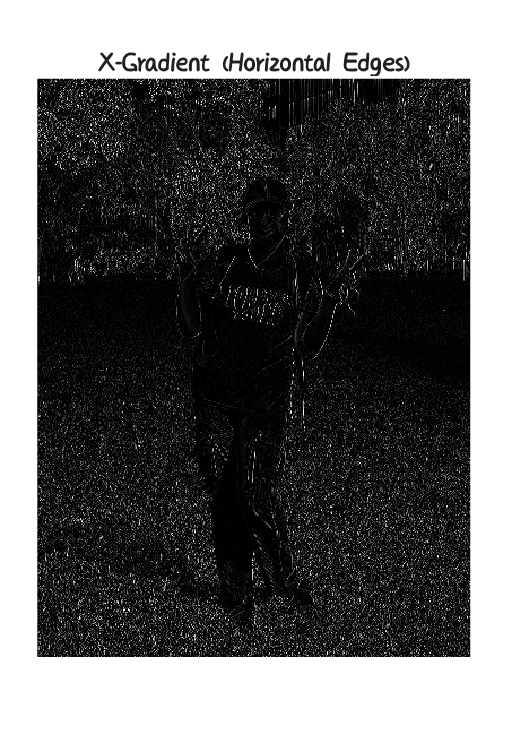

figure(1)
imshow(uint8(a1)) % The x-gradient image
title('X-Gradient (Horizontal Edges)')
exportgraphics(gcf, 'P1.png', 'Resolution', 300)


figure(2)
imshow(uint8(a2)) % The y-gradient image
title('Y-Gradient (Vertical Edges)')
exportgraphics(gcf, 'P2.png', 'Resolution', 300)


figure(3)
imshow(uint8(a3)) % Final gradient image
title('Combined Prewitt Edge Detection')
exportgraphics(gcf, 'P3.png', 'Resolution', 300)